## Centrale à Vapeur

Le fluide de travail **l'eau** subit un cycle de *Clausius-Rankine* dans une centrale à vapeur. La pression de l'évaporateur est de $p_V$ = 4,0 MPa, tandis que la pression dans le condenseur est de $p_C$ = 10 kPa. La température d'entrée dans la turbine est de $T_3$ = 450°C. L'eau entre dans la pompe sous forme de liquide en ébullition. Le rendement isentropique de la pompe est de 0.8 et celui de la turbine de 0.85.

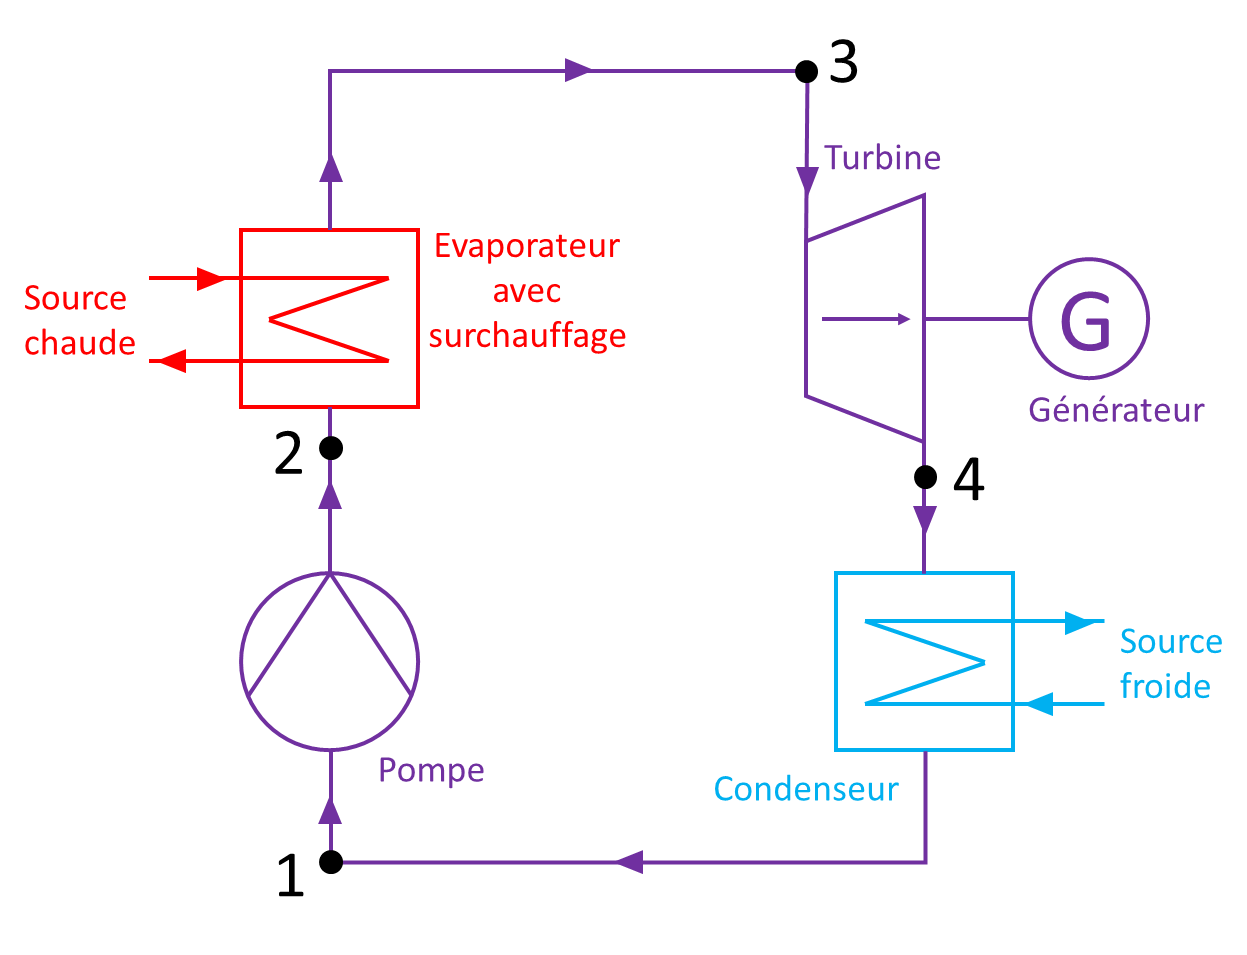

a) Y a-t-il de la vapeur surchauffée ou de la vapeur humide à la sortie de la turbine ? Tracer approximativement le diagramme P,h et le diagramme T,s du cycle.

% état 3
T_3 = 450+273.15; p_V=4000000; p_C = 10000;
h_3 = ADVENS_Props('h', 'P', p_V, 'T', T_3, 'H2O')

h_3 = 3.3298e+06

s_3 = ADVENS_Props('s', 'P', p_V, 'T', T_3, 'H2O')

s_3 = 6.9356e+03


% état 4
h_4s = ADVENS_Props('h', 's', s_3, 'P', p_C, 'H2O')

h_4s = 2.1970e+06

eta_turb = 0.85;
% rappel: eta_turb = (h_4 - h_3)/(h_4s - h_3)
h_4 = h_3 + (h_4s - h_3) * eta_turb

h_4 = 2.3670e+06

x_4 = ADVENS_Props('x', 'P', p_C, 'h', h_4, 'H2O')  % vapeur humide !

x_4 = 0.9092


s_4 = ADVENS_Props('s', 'P', p_C, 'h', h_4, 'H2O')

s_4 = 7.4682e+03

T_4 = ADVENS_Props('T', 'P', p_C, 'h', h_4, 'H2O')

T_4 = 318.9600

T_4s = ADVENS_Props('T', 's', s_3, 'P', p_C, 'H2O')

T_4s = 318.9600


% état 1
x_1=0;
T_1 = ADVENS_Props('T', 'P', p_C, 'x', x_1, 'H2O')

T_1 = 318.9600

h_1 = ADVENS_Props('h', 'P', p_C, 'x', x_1, 'H2O')

h_1 = 1.9126e+05

s_1 = ADVENS_Props('s', 'P', p_C, 'x', x_1, 'H2O')

s_1 = 648.4932


% état 2
h_2s = ADVENS_Props('h', 's', s_1, 'P', p_V, 'H2O')

h_2s = 1.9541e+05

eta_pompe = 0.8;
% rappel: eta_pompe = (h_2s - h_1)/(h_2 - h_1)
h_2 = h_1 + (h_2s - h_1)/eta_pompe

h_2 = 1.9644e+05


s_2 = ADVENS_Props('s', 'P', p_V, 'h', h_2, 'H2O')

s_2 = 651.7417

T_2 = ADVENS_Props('T', 'P', p_V, 'h', h_2, 'H2O')

T_2 = 319.3464

T_2s = ADVENS_Props('T', 's', s_1, 'P', p_V, 'H2O')

T_2s = 319.0976

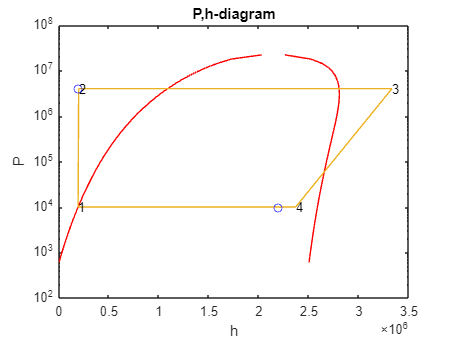

% plot P,h
logPh_diagram('H2O')
hold on;
plot([h_1 h_2 h_3 h_4 h_1], [p_C p_V p_V p_C p_C])
text(h_1, p_C, '1')
text(h_2, p_V, '2')
text(h_3, p_V, '3')
text(h_4, p_C, '4')
hold on;
plot([h_2s h_4s], [p_V p_C], 'bo')

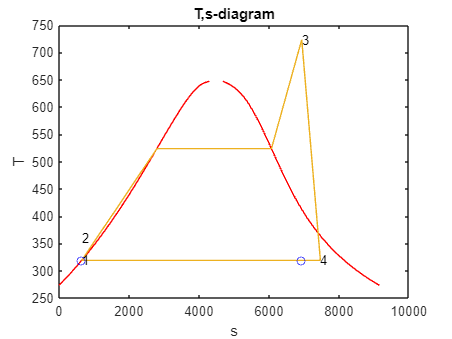

% plot T,s
Ts_diagram('H2O')
hold on;
T_2a = ADVENS_Props('T', 'P', p_V, 'x', 0, 'H2O');
s_2a = ADVENS_Props('s', 'P', p_V, 'x', 0, 'H2O');
s_2b = ADVENS_Props('s', 'P', p_V, 'x', 1, 'H2O');
plot([s_1 s_2 s_2a s_2b s_3 s_4 s_1], [T_1 T_2 T_2a T_2a T_3 T_4 T_1])
text(s_1, T_1, '1')
text(s_2, T_2+40, '2')
text(s_3, T_3, '3')
text(s_4, T_4, '4')
hold on;
plot([s_1 s_3], [T_4s T_2s], 'bo')

b) Calculer la chaleur spécifique apportée $q_{\textrm{in}}$ et la chaleur dissipée $q_{out}$ ainsi que le travail spécifique $w_{cyc}$ du cycle.

q_in = h_3 - h_2

q_in = 3.1334e+06

q_out = h_1 - h_4

q_out = -2.1757e+06

w_cyc = - (q_in + q_out)

w_cyc = -9.5766e+05

c) Quel est le rendement thermique $\eta_{th}$ ?

eta_th = - w_cyc/q_in

eta_th = 0.3056

d) Determiner les températures thermodynamiques moyennes $T^{moy}_{in}$ et $T^{moy}_{out}$ auxquelles la chaleur est apportée et dissipée. Rappel: $q_{AB} = \int_A^B T ds = T^{moy}\cdot(s_B-s_A)$

T_in = q_in / (s_3 - s_2)

T_in = 498.6345

T_out = q_out / (s_1 - s_4)

T_out = 319.0305

e) Calculer le rendement thermique du cycle de Carnot équivalent et le coefficient de qualité du cycle $\nu_{cyc}$ analysé.

eta_Carnot = 1 - T_out/T_in

eta_Carnot = 0.3602

nu_cyc = eta_th/eta_Carnot

nu_cyc = 0.8485